clear all;
% Load resistance-temperature data from CSV
% Assumes ntc.csv has two columns: temperature (°C) and resistance (Ohms)
data = csvread('ntc.csv');
t = data(:,1);       % Temperature in °C
r = data(:,2);       % Resistance in Ohms

% Constants
R5 = 10000;          % Series resistor in Ohms
adc_max = 1024;      % ADC resolution (10-bit)

% Calculate ADC values from voltage divider formula:

ad = (r ./ (r+10)) * 2^10;

% Plot temperature vs ADC value
figure;
plot(ad, t, 'bo');
xlabel('ADC Value');
ylabel('Temperature (°C)');
title('NTC Temperature vs ADC Value');
grid on;
hold on;


% Fit a 10th-order polynomial
p = polyfit(ad, t, 10);

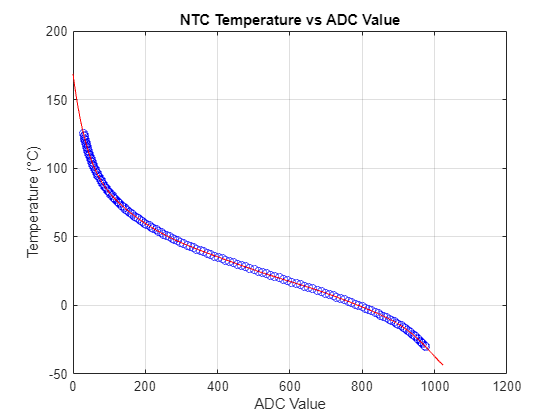


% Generate full ADC range and evaluate polynomial
ad2 = 0:1023;
t2 = round(polyval(p, ad2), 1);

plot(ad2, t2, 'r');


% Save the lookup table in tenths of a degree (as integers)
dlmwrite('data.dlm', t2 * 10, ',');
